% Jep Brinkmann Thesis HMM example
clc; close all;

Initiate the HMM

k = number of states

d = number of possible observational values

T = transition matrix

O = emission matrix

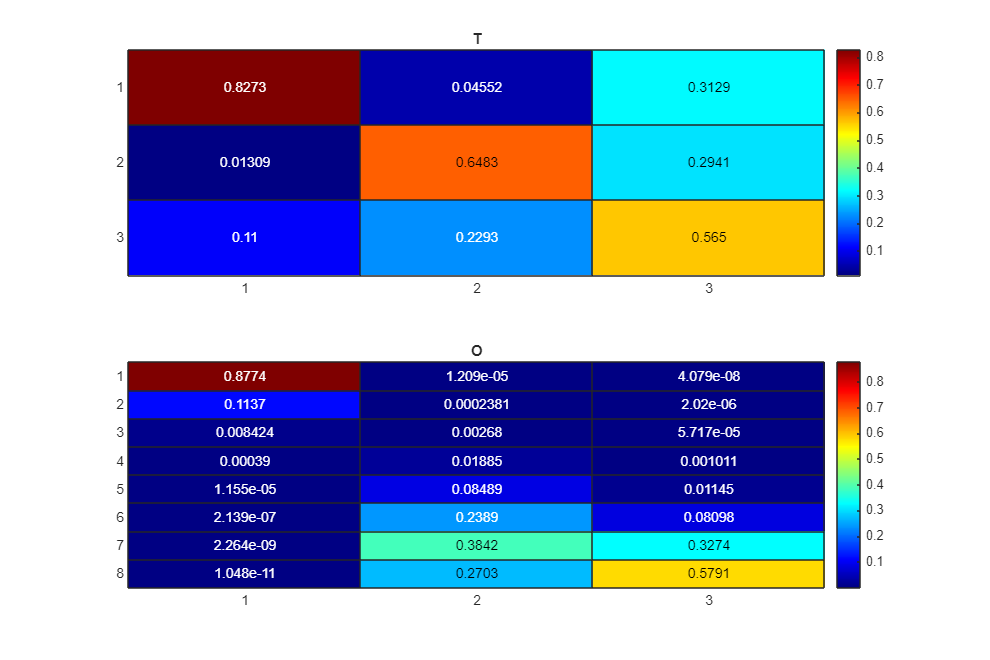

k = 3;
d = 8;

lam = 3;

T = lam * eye(k) + abs(randn(k, k));
T = diag(sum(T, 1)) \ T ;

O = zeros(d, k);

for i = 1:k
    O(:, i) = binopdf(1:d, d, rand);
end
O = Stochasticize(O);


if(rank(T) ~= k || rank(O) ~= k)
error("Insuffucient rank: Rank of T: " + rank(T) + " - and Rank of O: " + rank(O) + " - must be at least: " + k);
end

% k = 2;
% d = 6;
% 
% T = [.9 .1; .05 .95];
% 
% O = [1/6, 1/6, 1/6, 1/6, 1/6, 1/6;...
% 7/12, 1/12, 1/12, 1/12, 1/12, 1/12];

% 
% k = 3;
% d = 10;
% 
% T = [8/10, 1/15, 1/6; 
%     1/10, 13/15, 1/6; 
%     1/10, 1/15, 2/3];
% 
% O = [6/15, 1/20, 1/50;
%     1/15, 11/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 21/50;
%     1/15, 1/20, 21/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;]';

% k = 3;
% d = 8;
% 
% T = [8/10, 1/15, 1/6; 
%     1/10, 13/15, 1/6; 
%     1/10, 1/15, 2/3];
% 
% O = [6/15, 1/20, 1/50;
%     1/15, 11/20, 1/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 21/50;
%     1/15, 1/20, 21/50;
%     1/15, 1/20, 1/50;
%     1/15, 1/20, 1/50;
%     3/15, 3/20, 3/50;]';

figure('Renderer', 'painters', 'Position', [10 10 900 600])

subplot(2, 1, 1);
h = heatmap(T, Colormap=jet());
h.Title = 'T';

subplot(2, 1, 2);
h = heatmap(O, Colormap=jet());
h.Title = 'O';

eig(T)

ans =    1.000000000000001
   0.728836790341911
   0.530816559474111


L = zeros(k, k, d);

for i = 1:size(L, 1)
    for j = 1:size(L, 2)
        for l = 1:size(L, 3)
            L(i,j,l) = T(i,j) * O(l,j);
        end
    end
end


Generate an observational sequence based on the defined HMM

T_seq = 1e5;

[seq,states] = hmmgenerate(T_seq,T',O');

U{1} = (O * T);
U{2} = O;
U{3} = (O * T');

P3 = cpdgen(U);

Generate Probability Density Tensors

tic
M = ProbabilityTensorGenerate(seq, 3, d);
toc

Elapsed time is 0.896034 seconds.



ranks = [k, k]

ranks =      3     3



[G,rel_error] = TT_SVD(P3, 1e-15)

G = 1×4 cell array
    {8×7 double}    {7×8×7 double}    {7×8 double}    {[3]}


rel_error =      1.499474292067487e-17



G{1}

ans =   -0.078082270378118   0.293065430504688  -0.533971588356661  -0.020104150575682   0.421626718812118  -0.148086081279141  -0.188977361870740
  -0.146930144272462   0.551461235492437  -0.432396451266958   0.030817518973538  -0.600964231262211  -0.208793651677247   0.018568592696605
  -0.158296955036359   0.593509421467598   0.164374846452527  -0.007416819974684   0.323019878397242   0.664958886265356   0.129288399858114
  -0.108978650622950   0.398981610193005   0.543203846038305  -0.029981490539079   0.275261091213360  -0.669366012643641  -0.029156240012403
  -0.070337128283604   0.165470672931261   0.422961165926862   0.026299954849729  -0.510207996798472   0.141148988548677   0.139553692341117
  -0.161456022068846   0.004006275171573   0.157581663490389  -0.107988461545968  -0.134965840153358   0.153775612440012  -0.945050800349499
  -0.522232833525030  -0.141297735621120   0.002125637676819   0.839294669030161   0.048653704576997  -0.012920714344779  -0.015416432150838
  -0.79

G{2}

ans = ans(:,:,1) =

  -0.073663279216641  -0.139833113942071  -0.151988946551527  -0.105497714010063  -0.067731451701783  -0.151648708663889  -0.488570615974386  -0.743361128702535
   0.089095110928080   0.168286032646136   0.181800510407927   0.122429811261146   0.048399308164709  -0.015160663737863  -0.101053281898220  -0.157592356404910
  -0.000133570391316  -0.000123794273007   0.000007092618526   0.000101164790690   0.000085767121926   0.000033394868170   0.000002197881951  -0.000007021041410
   0.000000000000000   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000   0.000000000000000   0.000000000000000  -0.000000000000000
   0.000000000000000  -0.000000000000000  -0.000000000000000  -0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000  -0.000000000000000
  -0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000  -0.000000000000000   0.000000000000000
  -0.000000000

G{3}

ans =    0.045176604198437   0.086351950628231   0.094453015273094   0.065134705863229   0.033599284988390   0.040062384080004   0.113962521964973   0.172266503511619
   0.031267155898236   0.059467853946931   0.064690555343779   0.043846539609080   0.017233320191874  -0.006852999784282  -0.041407599666414  -0.064431700888398
  -0.000144889108843  -0.000118394058082   0.000042280236826   0.000145023520766   0.000113379558130   0.000042220624939   0.000000247188491  -0.000012768040210
  -0.000000000000000   0.000000000000000   0.000000000000000  -0.000000000000000  -0.000000000000000  -0.000000000000000   0.000000000000000   0.000000000000000
  -0.000000000000000   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000  -0.000000000000000  -0.000000000000000   0.000000000000000
  -0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000  -0.000000000000000  -0.000000000000000  -0.000000000000000   0.000000000000000
  -0.000000000000000  -0.000